tlon=ncread('OCIM2_48L_base_data.nc','tlon');
tlat=ncread('OCIM2_48L_base_data.nc','tlat');
tlat1d=squeeze(squeeze(tlat(:,1,1)));
tlon1d=squeeze(squeeze(tlon(1,:,1)));
ulon=ncread('OCIM2_48L_base_data.nc','ulat');
ulat=ncread('OCIM2_48L_base_data.nc','ulon');
ulat1d=squeeze(squeeze(ulat(:,1,1)));
ulon1d=squeeze(squeeze(ulon(1,:,1)));




ocnmask=ncread('OCIM2_48L_base_data.nc','ocnmask');
output=load('OCIM2_CTL_He');
TR=load('OCIM2_48L_base_transport','TR');
vvel=ncread('OCIM2_48L_base_data.nc','vvel');
uvel=ncread('OCIM2_48L_base_data.nc','uvel');
TR=TR.TR;
output=output.output;
Pacificmask=zeros(size(tlon));
Pacificmaskold=output.MSKS.PAC;
[Ny,Nx,Nz]=size(Pacificmask);
for ix=1:Nx
    for iy=1:Ny
        for iz=1:Nz
%             if tlon(iy,ix,iz)>121 && tlon(iy,ix,iz)<291
%                  if tlat(iy,ix,iz)<70 && tlat(iy,ix,iz)>-40
%                       if ~(tlat(iy,ix,iz)<-31 && tlon(iy,ix,iz)<150)&&~(tlat(iy,ix,iz)>68 && tlon(iy,ix,iz)>240)&&~(tlat(iy,ix,iz)>17.8 && tlon(iy,ix,iz)>259)&&~(tlat(iy,ix,iz)>8&& tlon(iy,ix,iz)>276)
                       if(Pacificmaskold(iy,ix,1)==1)
                          Pacificmask(iy,ix,iz)=ocnmask(iy,ix,iz);
                      end
                 %end
            %end
        end
    end
end


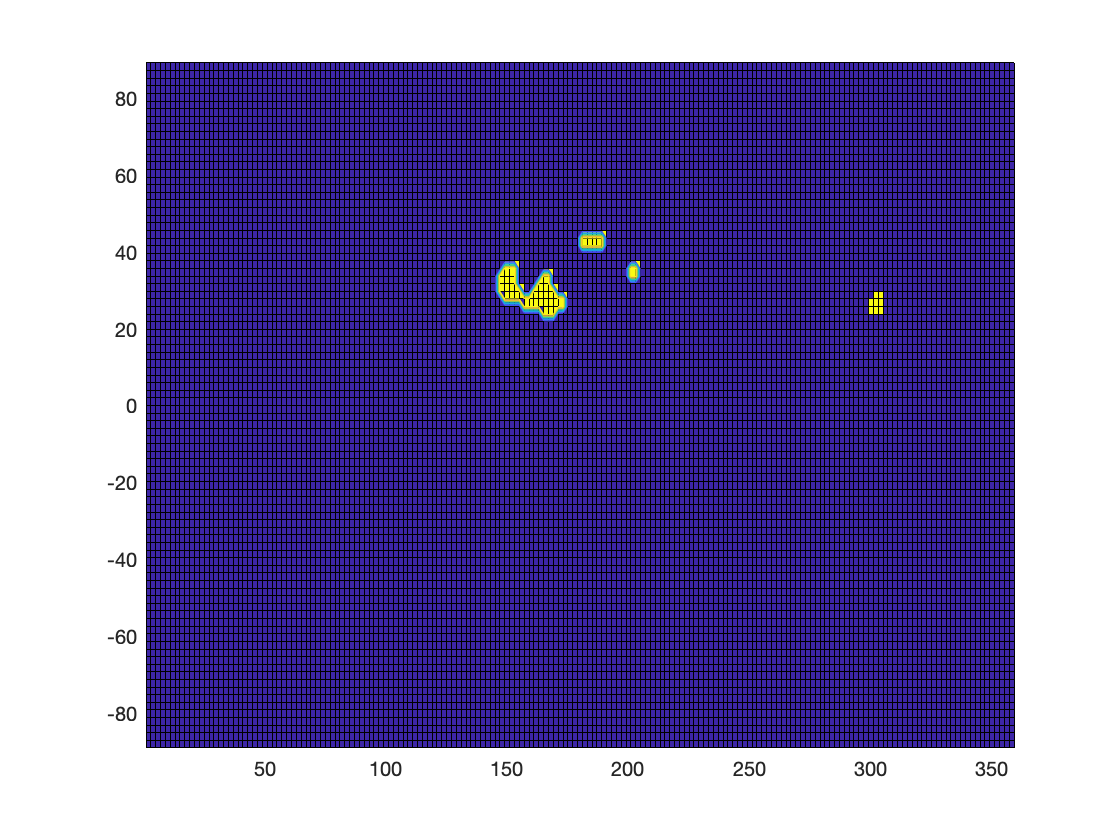


%%
iz=48;
figure
pcolor(tlon(:,:,iz),tlat(:,:,iz),ocnmask(:,:,iz));
hold on
contour(tlon(:,:,iz),tlat(:,:,iz),Pacificmask(:,:,iz));

%%

% pcolor(tlon(:,:,iz),tlat(:,:,iz),ocnmask(:,:,10));
% hold on;
% contour(tlon(:,:,1),tlat(:,:,1),Pacificmaskold(:,:,18));

%%

salt=ncread('OCIM2_48L_base_data.nc','salt');
ptemp=ncread('OCIM2_48L_base_data.nc','ptemp');
pd=calc_pd(salt,ptemp,2000)-1000;
tz=ncread('OCIM2_48L_base_data.nc','tz');
rho0=1000;
p3d=rho0*9.81*tz;

%gamman=eos80_legacy_gamma_n(salt(:),ptemp(:),p3d(:)/1e4,tlon(:),tlat(:));
%gamman=reshape(gamman,Ny,Nx,Nz);

%%
iy=51;
figure;

plotmap=squeeze(vvel(iy,:,:));
pcolor(squeeze(tlon(iy,:,:)),squeeze(tz(iy,:,:)),plotmap);
hold on
contour(squeeze(tlon(iy,:,:)),squeeze(tz(iy,:,:)),squeeze(pd(iy,:,:)),[32 35.5 36 36.5 36.9 37 37.04 37.07 ],'linewidth',2,'showtext','on');
axis ij
%colormap
caxis([-0.05,0.05]);

cmap=cbrewer('div','RdBu',22);

 
----------------------------------------------------------------------
The maximum number of colors for table *RdBu* is 11
The new colormap will be extrapolated from these 11 values
----------------------------------------------------------------------
 


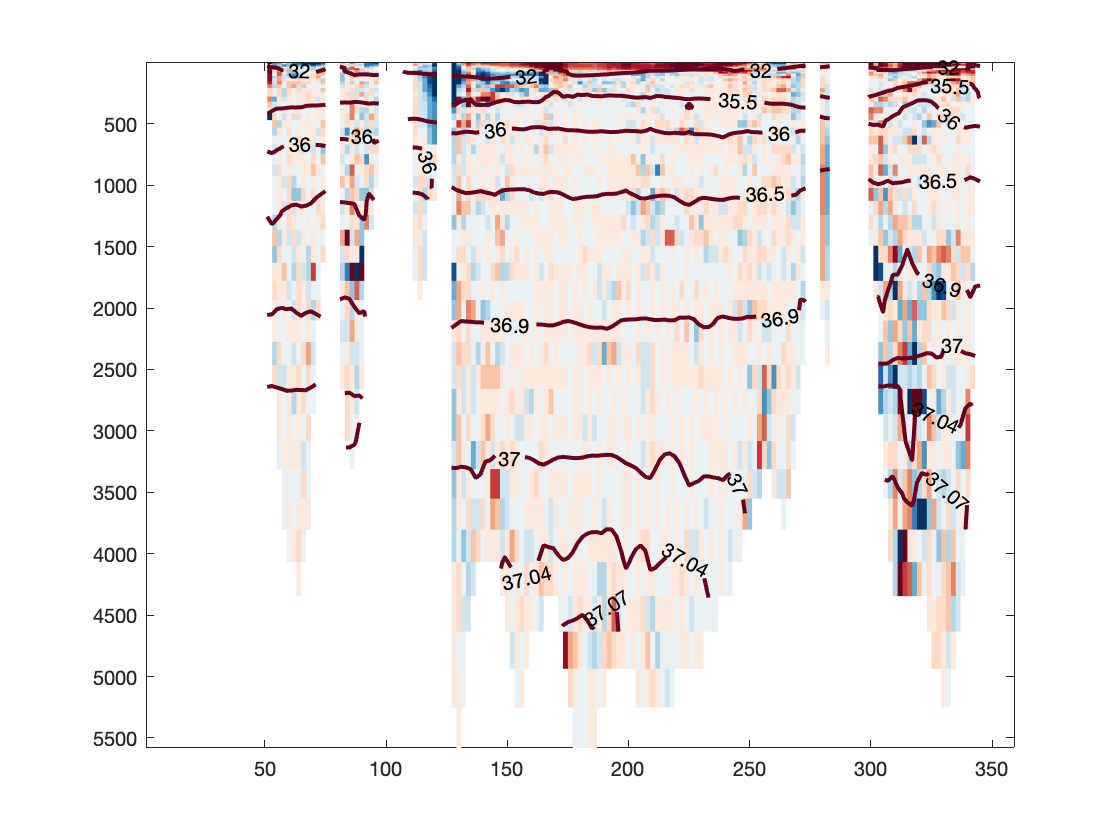

cmap=cmap([end:-1:13 10:-1:1],:);
cmap(cmap>1)=1;cmap(cmap<0)=0;
colormap(cmap)
shading flat

%% Calculate age by transporting
%Age
tau=10/(24*3600*365); %10s
Ls=zeros(size(ocnmask));
Omgs=zeros(size(ocnmask));
for ix=1:Nx
    for iy=1:Ny
        Ls(iy,ix,iz)=ocnmask(iy,ix,iz)/tau; 
        Omgs(iy,ix,iz)=ocnmask(iy,ix,iz);
    end
end
Ls=Ls(ocnmask==1);
Ls=diag(sparse(Ls));
Omgs=Omgs(ocnmask==1);
Ts=TR+Ls;
Ws=zeros(size(ocnmask));
tlon=ncread('OCIM2_48L_base_data.nc','tlon');
ulon=ncread('OCIM2_48L_base_data.nc','ulat');
tlat=ncread('OCIM2_48L_base_data.nc','tlat');
ulat=ncread('OCIM2_48L_base_data.nc','ulon');
wz=ncread('OCIM2_48L_base_data.nc','wz');
tz=ncread('OCIM2_48L_base_data.nc','tz');
depthg=(tz-wz)*2;
area=ncread('OCIM2_48L_base_data.nc','area');
VOL=ncread('OCIM2_48L_base_data.nc','vol');
grid.DXT3d=repmat(output.grid.DXT3d,1,1,2);
grid.DYT3d=repmat(output.grid.DYT3d,1,1,2);
grid.DZT3d=(tz-wz)*2;
% myarea=grid.DXT3d.*grid.DYT3d;
% myDZT3d=VOL./area;
% myarea1d=myarea(:,1,1);
% area1d=area(:,1,1);
%myarea1d-area1d
%myDZT1d=squeeze(squeeze(myDZT3d(1,1,:)));
%errordzt=(myDZT1d-DZT)./DZT;

kdiapycnal=ncread('OCIM2_48L_base_data.nc','kappa_perp');
kisopycnal=ncread('OCIM2_48L_base_data.nc','kappa_para');
for ix=1:Nx
    for iy=1:Ny
        for iz=1:Nz
          Ws(iy,ix,iz)= area(iy,ix,iz)*depthg(iy,ix,iz);
        end
    end
end

N-dimensional indexing allowed for full matrices only.


Ws=Ws(ocnmask==1);
Ws=diag(sparse(Ws));

R=6371000;

%%
DZT=squeeze(grid.DZT3d(1,1,:));
DYT=grid.DYT3d(:,:,1);
DXT=grid.DXT3d(:,:,1);
area2d=area(:,:,1);
dxdy=DXT.*DYT;
%% calc_pd
%%
lp1=age_TRg;

 %[lp1,fp1,lp2,fp2] = eqage(TR,grid,ocnmask);
%%
figure;
iy=46;
cmap=hot(20);
plotmap=squeeze(lp1(iy,:,:));
pcolor(squeeze(tlon(iy,:,:)),squeeze(tz(iy,:,:)),plotmap);
hold on
contour(squeeze(tlon(iy,:,:)),squeeze(tz(iy,:,:)),squeeze(pd(iy,:,:)),[32 35.5 36 36.5 36.9 37 37.04 37.07 ],'b','linewidth',2,'showtext','on');
axis ij
colorbar

caxis([0,2000]);
cmap=cmap([end:-1:13 10:-1:1],:);
cmap(cmap>1)=1;cmap(cmap<0)=0;
colormap(cmap)
shading flat

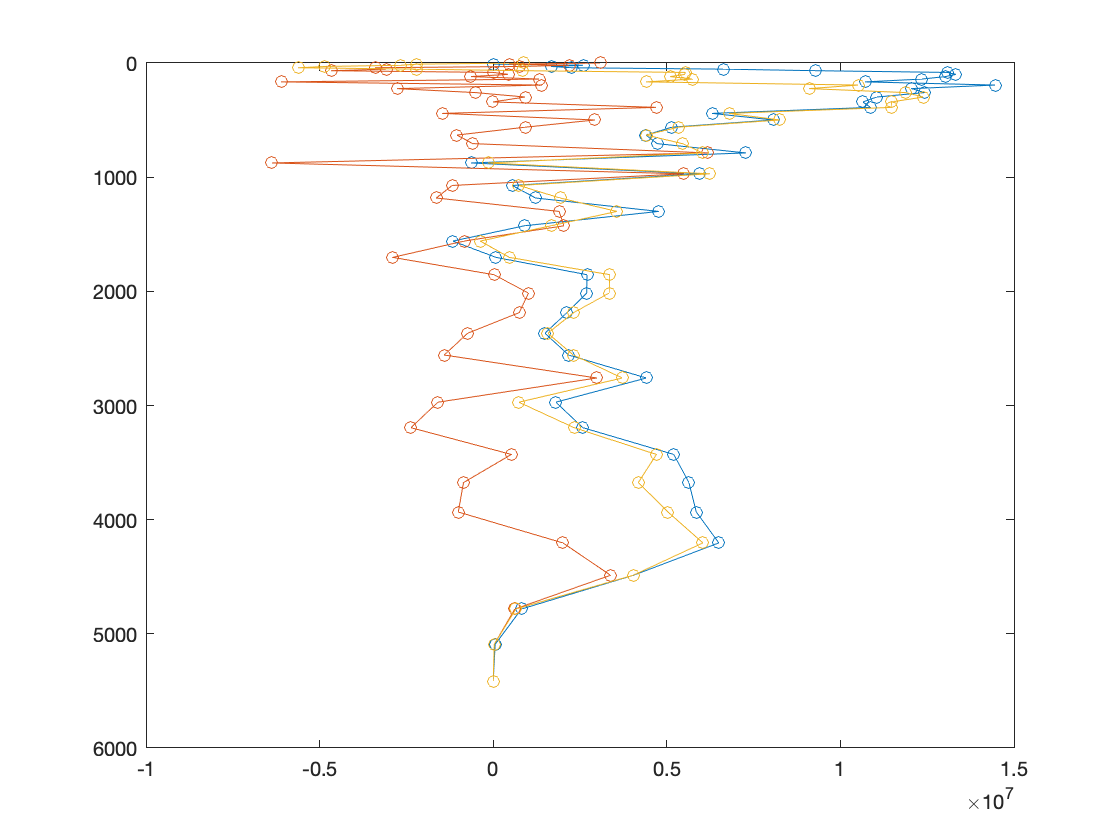


%%
idepth=38;
iysouth=46;
iynorth=75;
wvel=ncread('OCIM2_48L_base_data.nc','wvel');



Vvolup=zeros(Nz,1);
agevolup=zeros(Nz,1);
agedifup=zeros(Nz,1);
for ix=1:Nx
    for iy=iysouth:iynorth
        for iz=1:Nz
            if(Pacificmask(iy,ix,iz)==1)
            Vvolup(iz)=Vvolup(iz)+wvel(iy,ix,iz)*area(iy,ix,iz);
            end
        end
    end
end


for ix=1:Nx
    for iy=iysouth:iynorth
        for iz=1:Nz
            if(Pacificmask(iy,ix,iz)==1)
                if iz==1||isnan(lp1(iy,ix,iz-1))
                   mage=lp1(iy,ix,iz); 
                   dzage=0;
                else
                   mage=(lp1(iy,ix,iz)+lp1(iy,ix,iz-1))/2;
                   dzage=(lp1(iy,ix,iz)-lp1(iy,ix,iz-1));
                end
                agevolup(iz)=agevolup(iz)+wvel(iy,ix,iz)*area(iy,ix,iz)*lp1(iy,ix,iz);
                agedifup(iz)=agedifup(iz)+kdiapycnal(iy,ix,iz)*dzage/grid.DZT3d(iy,ix,iz)*area(iy,ix,iz);
            end
        end
    end
end

Vvolsouth=zeros(Nz,1);

for ix=1:Nx
    for iy=iysouth
        for iz=1:Nz
            if(Pacificmask(iy,ix,iz)==1)&&~isnan(vvel(iy,ix,iz))
            Vvolsouth(iz)=Vvolsouth(iz)+vvel(iy,ix,iz)*grid.DXT3d(iy,ix,iz)*grid.DZT3d(iy,ix,iz);
            
            end
        end
    end
end

Vvolsouthacc=cumsum(Vvolsouth,'reverse');

figure
plot(Vvolup,squeeze(squeeze(wz(1,1,:))),'o-');
axis ij
hold on

plot(Vvolsouth,squeeze(squeeze(wz(1,1,:))),'o-');
plot(Vvolsouthacc,squeeze(squeeze(wz(1,1,:))),'o-');

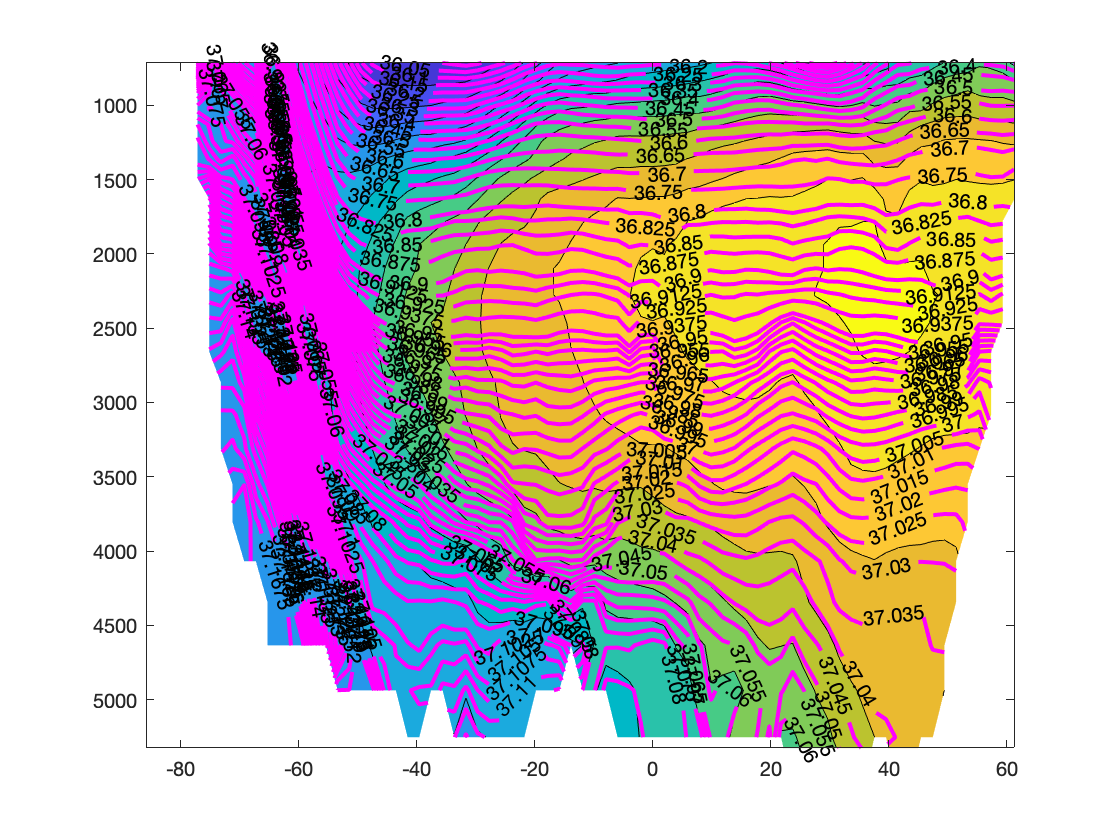

 
%% zonal age
VOL=area.*grid.DZT3d;
agepac=lp1.*Pacificmask.*VOL;
agepac=squeeze(nansum(agepac,2))./squeeze(nansum(Pacificmask.*VOL,2));
gammapac=pd.*Pacificmask.*VOL;%gamman.*Pacificmask.*VOL;
gammapac=squeeze(nansum(gammapac,2))./squeeze(nansum(Pacificmask.*VOL,2));
gammapac=pd.*Pacificmask.*VOL;%gamman.*Pacificmask.*VOL;
gammapac=squeeze(nansum(gammapac,2))./squeeze(nansum(Pacificmask.*VOL,2));
figure;
contourf(squeeze(tlat(:,1,:)),squeeze(tz(:,1,:)),agepac,[0:100:1500]);
axis ij;
hold on;
%contour(squeeze(tlat(:,1,:)),squeeze(tz(:,1,:)),gammapac,[27.4,27.8,28.04,28.1,28.2,28.3],'m','showtext','on','linewidth',2);
pdarray=[29:0.5:33 33.25:0.25:35 35.1:0.1:36  36.05:0.05:36.8 36.825:0.025:36.9 36.9125:0.0125:36.95 36.955:0.005:37.1 37.1025:0.0025:37.2];
contour(squeeze(tlat(:,1,:)),squeeze(tz(:,1,:)),gammapac,pdarray,'m','showtext','on','linewidth',2);



izt_psz_bottom=38;
izt_psz_top=31;
iyt_psz_south=46;
%iyt_bsz_north=
PSZmask=Pacificmask;
PSZmask(1:iyt_psz_south-1,:,:)=0; 
PSZmask(:,:,1:izt_psz_top-1)=0;
PSZmask(:,:,izt_psz_bottom+1:end)=0;

%Pacific Shadow zone (age) tracer flux budget
figure
agepsz=lp1;

Unrecognized function or variable 'lp1'.

agepsz(PSZmask==0)=nan;
wvelpsz=wvel;
wvelpsz(PSZmask==0)=nan;
cmap=cbrewer('div','RdBu',22);
dwz=wz(:,:,1:end-1)-wz(:,:,2:end);
agepsz_top_at_w=(agepsz(:,:,izt_psz_top-1).*dwz(:,:,izt_psz_top-1)+agepsz(:,:,izt_psz_top).*dwz(:,:,izt_psz_top))./(dwz(:,:,izt_psz_top-1)+dwz(:,:,izt_psz_top)); %simple averaege here, should be weighted by grid size
agepsz_top_at_w=agepsz(:,:,izt_psz_top-1);
agepsz_top_at_w1=agepsz(:,:,izt_psz_top);
agepsz_top_at_w(wvel(:,:,izt_psz_top)>0)=agepsz_top_at_w1(wvel(:,:,izt_psz_top)>0);
ageadv_psz_top=wvel(:,:,izt_psz_top).*agepsz_top_at_w.*area(:,:,izt_psz_top)*31104000;
ageadv_psz_top_tot=nansum(ageadv_psz_top,'all')
agepsz_bottom_at_w=(agepsz(:,:,izt_psz_bottom).*dwz(:,:,izt_psz_bottom)+agepsz(:,:,izt_psz_bottom+1).*dwz(:,:,izt_psz_bottom+1))./(dwz(:,:,izt_psz_bottom+1)+dwz(:,:,izt_psz_bottom)); %simple averaege here, should be weighted by grid size
agepsz_bottom_at_w=agepsz(:,:,izt_psz_bottom);
agepsz_bottom_at_w1=agepsz(:,:,izt_psz_bottom+1);
agepsz_bottom_at_w(wvel(:,:,izt_psz_bottom+1)>0)=agepsz_bottom_at_w1(wvel(:,:,izt_psz_bottom+1)>0);
ageadv_psz_bottom=wvel(:,:,izt_psz_bottom+1).*agepsz_bottom_at_w.*area(:,:,izt_psz_bottom)*31104000;
ageadv_psz_bottom_tot=nansum(ageadv_psz_bottom,'all')

VOLpsz=nansum(VOL.*PSZmask,'all')

cmap=cmap([end:-1:13 10:-1:1],:);
cmap(cmap>1)=1;cmap(cmap<0)=0;
%agepac_psz_bottom=squeeze(lp1(:,:,izt_psz_bottom));
subplot(2,2,1)
contourf(squeeze(tlon(:,:,izt_psz_bottom)),squeeze(tlat(:,:,izt_psz_bottom)),squeeze(agepsz(:,:,izt_psz_bottom)));
colorbar;
subplot(2,2,3)
contourf(squeeze(tlon(:,:,izt_psz_bottom)),squeeze(tlat(:,:,izt_psz_bottom)),squeeze(wvelpsz(:,:,izt_psz_bottom)));
colorbar;
caxis([-5e-6,5e-6])
colormap(gca, cmap)
subplot(2,2,2)
contourf(squeeze(tlon(:,:,izt_psz_top)),squeeze(tlat(:,:,izt_psz_top)),squeeze(agepsz(:,:,izt_psz_top)));
colorbar;
subplot(2,2,4)
contourf(squeeze(tlon(:,:,izt_psz_top)),squeeze(tlat(:,:,izt_psz_top)),squeeze(wvelpsz(:,:,izt_psz_top)));
colorbar;
colormap(gca, cmap)
caxis([-5e-6,5e-6])
age_at_v=zeros(size(lp1));
lp1south=lp1(1:end-1,:,:);
lp1north=lp1(2:end,:,:);
vvelsmall=vvel(1:end-1,:,:);
age_at_v_small=lp1south;
age_at_v_small(vvelsmall<0)=lp1north(vvelsmall<0);
age_at_v(1:end-1,:,:)=age_at_v_small;
%age_at_v(1:end-1,:,:)=(lp1(1:end-1,:,:)+lp1(2:end,:,:))/2; % at v1 to vN-1
%age_at_v=zeros(size(lp1));
%age_at_v=lp1;
%age_at_v(vvel<0)=lp1(vvel<0)
age_flux_v=age_at_v.*vvel.*grid.DXT3d.*repmat(reshape(DZT,[1,1,Nz]),[Ny,Nx,1]);
age_flux_psz=age_flux_v*31104000;
age_flux_psz(PSZmask==0)=nan;
age_flux_psz_south=squeeze(age_flux_psz(iyt_psz_south,:,:));
figure
pcolor(age_flux_psz_south)
age_flux_psz_south_tot=nansum(age_flux_psz_south,'all')




% transport Tsb=TR+Ls+Lb; 
% here zone a is whole surface s, zone b is PSZ
% we are gonna calculate fa down
tau=10/365.25/86400; %10s to yr
%Omgs=zeros(size(ocnmask));
%Omgs(:,:,1)=ocnmask(:,:,1);
%iocn=find(ocnmask(:)==1);
%Omgs=Omgs(iocn);
%Ls=d0(Omgs)/tau;
%LPSZ=d0(PSZmask(iocn))/tau; %Lb
%Tsurface_PSZ=TR+Ls+LPSZ;
%REG = 0*ocnmask;
%REG(:) = 1; % latitudes south of 65oS
ocnmask=M3d;
maska=0*ocnmask;
maska(:,:,1)=1;
maska=maska.*ocnmask;
maskb=PSZmask;

maskbvec=d0(maskb(iocn));
TRb=TR-maskbvec/tau;
fracPSZtau=myeq_wmfrac(TRb,maska,maskb*0,ocnmask); % ventilation fractions;


%F = myeq_wmfrac(TR,maska,maskb,ocnmask); % ventilation fractions
%fracPSZ=F;
%tempfracPSZ=fracPSZ;
tempfracPSZ=fracPSZ.*Pacificmask;
tempfracPSZ(Pacificmask==0)=nan;
zonalmeantempfracPSZ=squeeze(nanmean(tempfracPSZ,2));
iztemp=izt_psz_bottom+1;
contourf(squeeze(tlat(:,1,:)),squeeze(tz(:,1,:)),zonalmeantempfracPSZ);
axis ij;
colorbar()
tempfrac=fracPSZ.*Pacificmask;
tempfrac(1:iyt_psz_south-1,:,:)=tempfrac(1:iyt_psz_south-1,:,:)*0;
fracPSZ_bottom=tempfrac(:,:,izt_psz_bottom+1);
fracPSZ_bottom_at_w=fracPSZ_bottom;

fracPSZ_bottom_at_w=(tempfrac(:,:,izt_psz_bottom+1).*dwz(:,:,izt_psz_bottom+1)+tempfrac(:,:,izt_psz_bottom).*dwz(:,:,izt_psz_bottom))./(dwz(:,:,izt_psz_bottom)+dwz(:,:,izt_psz_bottom+1));
%fracPSZ_bottom_at_w(fracPSZ_bottom_at_w>0)=1;
%fracPSZ_bottom_at_w(wvel(:,:,izt_psz_bottom+1)<0)=0;
vent_flux_PSZ_bottom=wvel(:,:,izt_psz_bottom+1).*fracPSZ_bottom_at_w.*area(:,:,izt_psz_bottom+1);
%fracPSZ_bottom_at_w(tlat<0)=0;
vent_flux_PSZ_bottom_tot=nansum(vent_flux_PSZ_bottom,"all")
fracPSZ_top=tempfrac(:,:,izt_psz_top-1);
fracPSZ_top_at_w=fracPSZ_top;
%fracPSZ_bottom_at_w(wvel(:,:,izt_psz_top)>0)=0;
fracPSZ_top_at_w=(tempfrac(:,:,izt_psz_top-1).*dwz(:,:,izt_psz_top-1)+tempfrac(:,:,izt_psz_top).*dwz(:,:,izt_psz_top))./(dwz(:,:,izt_psz_top)+dwz(:,:,izt_psz_top-1));
%fracPSZ_top_at_w=(tempfrac(:,:,izt_psz_top-1)+tempfrac(:,:,izt_psz_top))/2;
%fracPSZ_top_at_w(fracPSZ_top_at_w>0)=1;
vent_flux_PSZ_top=wvel(:,:,izt_psz_top).*fracPSZ_top_at_w.*area(:,:,izt_psz_top);
vent_flux_PSZ_top_tot=nansum(vent_flux_PSZ_top,"all")
tempfrac=fracPSZ.*Pacificmask;
fracPSZ_south_at_v=(tempfrac(iyt_psz_south-1,:,:)+tempfrac(iyt_psz_south,:,:))/2;
fracPSZ_south_at_v=tempfrac(iyt_psz_south-1,:,:);
fracPSZ_south_at_v(vvel(iyt_psz_south-1,:,:)<0)=0;

vent_flux_PSZ_south=vvel(iyt_psz_south-1,:,:).*(grid.DXT3d(iyt_psz_south-1,:,:)+grid.DXT3d(iyt_psz_south,:,:))/2.*grid.DZT3d(iyt_psz_south-1,:,:).*fracPSZ_south_at_v;
vent_flux_PSZ_south(:,:,1:izt_psz_top-1)=0;
vent_flux_PSZ_south(:,:,izt_psz_bottom+1:end)=0;
vent_flux_PSZ_south_tot=nansum(vent_flux_PSZ_south,"all")
figure
contourf(squeeze(vent_flux_PSZ_south))

figure
iztemp=izt_psz_bottom+1;
contourf(squeeze(tlon(:,:,iztemp)),squeeze(tlat(:,:,iztemp)),squeeze(fracPSZ_bottom_at_w));
colorbar

iocn=find(ocnmask(:)==1);
isurf = find(ocnmask(:,:,1)==1);
iint = setdiff(iocn,isurf);
latgridid=1:91;
longridid=1:180;
zgridid=1:48;
[lonid3d,latid3d,zid3d]=meshgrid(longridid,latgridid,zgridid);
latidvec=latid3d(iocn);
lonidvec=lonid3d(iocn);
zidvec=zid3d(iocn);



tempid=281328;

trtemp=TR(tempid,:);
latidvec(tempid)
tlat(latidvec(tempid),1,1)
lonidvec(tempid)
tlon(1,lonidvec(tempid),1)
zidvec(tempid)
tz(1,1,zidvec(tempid))
tempid=281328;
latidvec(tempid)
tlat(latidvec(tempid),1,1)
lonidvec(tempid)
tlon(1,lonidvec(tempid),1)
zidvec(tempid)
tz(1,1,zidvec(tempid))
tempid=309168;
latidvec(tempid)
tlat(latidvec(tempid),1,1)
lonidvec(tempid)
tlon(1,lonidvec(tempid),1)
zidvec(tempid)
tz(1,1,zidvec(tempid))


FracPSZ_tendency=TR*fracPSZ(ocnmask==1);
FracPSZ_tendency_3D=ocnmask*nan;
FracPSZ_tendency_3D(ocnmask==1)=FracPSZ_tendency;
FracPSZ_tendency_3D=FracPSZ_tendency_3D.*VOL;
temptendency=FracPSZ_tendency_3D.*Pacificmask;
temptendency(tlat<0)=temptendency(tlat<0)*0;
figure
iztemp=izt_psz_bottom;
contourf(squeeze(tlon(:,:,iztemp)),squeeze(tlat(:,:,iztemp)),squeeze(temptendency(:,:,iztemp)));
colorbar()
total_tendency_bottom=nansum(temptendency(48:end,:,izt_psz_bottom-1:izt_psz_bottom)/365/86400,'all')

NPacmask=Pacificmask;
iyt_psz_south=47;
NPacmask(1:iyt_psz_south-1,:,:)=0; 
wfluxmask=wvel.*area.*ocnmask;
wfluxNpac=wvel.*area.*NPacmask;
figure
iztemp=izt_psz_bottom;
contourf(squeeze(tlon(:,:,iztemp)),squeeze(tlat(:,:,iztemp)),squeeze(wfluxNpac(:,:,iztemp)));
wfluxNpac_zprofile=nansum(nansum(wfluxNpac,1),2);
figure
plot(squeeze(squeeze(wfluxNpac_zprofile)),squeeze(squeeze(wz(1,1,:))),'o-')
axis ij
vflux=vvel.*grid.DZT3d.*grid.DXT3d;
vfluxpac=vflux.*Pacificmask;
izt_psz_bottom=38;
izt_psz_top=31;
vfluxpac_PSZ=nansum(vfluxpac(46,:,izt_psz_top:izt_psz_bottom),'all')

Sxz3d=grid.DZT3d.*grid.DXT3d;
Syz3d=grid.DZT3d.*grid.DYT3d;
%tracer=fracPSZ;
%tracer_periodx=cat(2,tracer,tracer(:,1,:));
%tracer_gradx=tracer(:,2:end,:)-tracer(:,1:end-1,:)./grid.DXT3d; %on ulon grids
%tracer_isodiff_x=-kisopycnal.*tracer_gradx;
transportisox=kisopycnal./grid.DXT3d.*Syz3d./VOL*365*86400;
transportisox(56,147,30)
transportisox(56,148,30)
transportadvx=uvel.*Syz3d./VOL*365*86400;
transportadvx(56,147,30)
transportadvx(56,148,30)

iztemp=3
subplot(2,2,1)
contourf(squeeze(ulon(:,:,iztemp)),squeeze(ulat(:,:,iztemp)),squeeze(uvel(:,:,iztemp)));
colorbar()
subplot(2,2,2)
contourf(squeeze(ulon(:,:,iztemp)),squeeze(ulat(:,:,iztemp)),squeeze(vvel(:,:,iztemp)));
colorbar()
iztemp=26
subplot(2,2,3)
contourf(squeeze(ulon(:,:,iztemp)),squeeze(ulat(:,:,iztemp)),squeeze(uvel(:,:,iztemp)));
colorbar()
subplot(2,2,4)
contourf(squeeze(ulon(:,:,iztemp)),squeeze(ulat(:,:,iztemp)),squeeze(vvel(:,:,iztemp)));
colorbar()
colormap(cmap)
caxis([-0.3,0.3])


cmap=cbrewer('div','RdBu',22);

 
----------------------------------------------------------------------
The maximum number of colors for table *RdBu* is 11
The new colormap will be extrapolated from these 11 values
----------------------------------------------------------------------
 


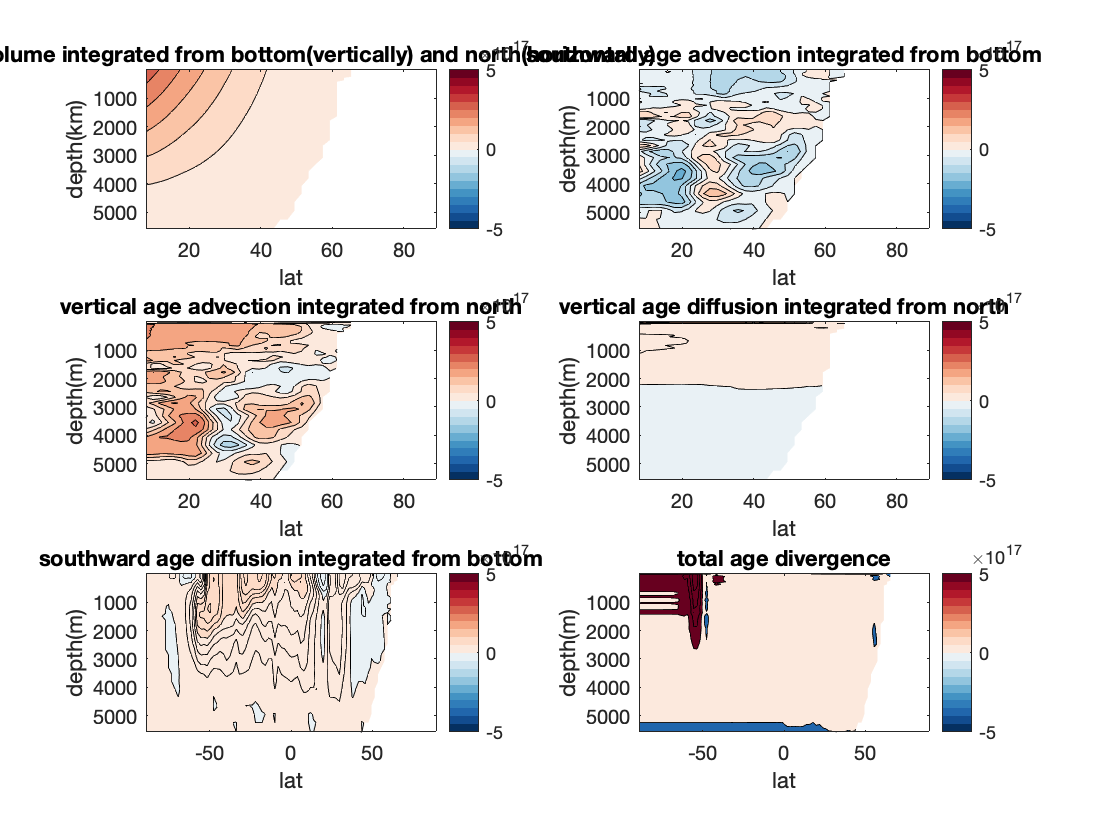

cmap=cmap([end:-1:13 10:-1:1],:);
cmap(cmap>1)=1;cmap(cmap<0)=0;

%pacific meridional age flux
% age_at_v=zeros(size(lp1));
% age_at_v(1:end-1,:,:)=(lp1(1:end-1,:,:)+lp1(2:end,:,:))/2; % at v1 to vN-1
% age_flux_v=age_at_v.*vvel.*grid.DXT3d.*repmat(reshape(DZT,[1,1,Nz]),[Ny,Nx,1]);
% age_flux_v(isnan(age_flux_v))=0;
age_flux_v=ageADVy3d;
cum_age_flux_v=squeeze(sum(Pacificmask.*age_flux_v,2));
cum_age_flux_v=cumsum(cum_age_flux_v,2,'reverse'); % Zsum
%pacific zonal age flux
% age_at_w=zeros(size(lp1));
% age_at_w(:,:,2:end)=(lp1(:,:,1:end-1)+lp1(:,:,2:end))/2;
% age_flux_w=age_at_w.*wvel.*area;
% age_flux_w(isnan(age_flux_w))=0;
age_flux_w=ageADVz3d;
cum_age_flux_w=squeeze(sum(Pacificmask.*age_flux_w,2));
cum_age_flux_w=cumsum(cum_age_flux_w,1,'reverse'); % Zsum
% age_grad_y=zeros(size(lp1));
% age_grad_y(1:end-1,:,:)=(-lp1(1:end-1,:,:)+lp1(2:end,:,:)); % at v1 to vN-1
% age_diff_y=-kisopycnal.*age_grad_y./grid.DYT3d.*grid.DXT3d.*repmat(reshape(DZT,[1,1,Nz]),[Ny,Nx,1]);

% age_grad_z=zeros(size(lp1));
% age_grad_z(:,:,2:end)=(-lp1(:,:,1:end-1)+lp1(:,:,2:end)); % at w2 to wN
% age_diff_z=-kdiapycnal.*age_grad_z./(-repmat(reshape(DZT,[1,1,Nz]),[Ny,Nx,1])).*area;
% age_diff_z(isnan(age_diff_z))=0;
% age_diff_y(isnan(age_diff_y))=0;
age_diff_y=ageD2yflux3d;
age_diff_z=ageDIFDflux3d;
cum_age_diff_y=squeeze(sum(Pacificmask.*age_diff_y,2));
cum_age_diff_y=cumsum(cum_age_diff_y,2,'reverse');
cum_age_diff_z=squeeze(sum(Pacificmask.*age_diff_z,2));
cum_age_diff_z=cumsum(cum_age_diff_z,1,'reverse'); % Zsum

% Volume integrated in Pac
figure
cumvolume=squeeze(sum(Pacificmask.*VOL,2));
cumvolume=cumsum(cumvolume,2,'reverse');
cumvolume=cumsum(cumvolume,1,'reverse');
subplot(3,2,1)
plotdata=cumvolume./cumvolume.*cumvolume;
latarray=50:91;
contourf(squeeze(tlat(latarray,1,:)),squeeze(tz(latarray,1,:)),plotdata(latarray,:))
axis ij
colorbar
caxis([-5e17,5e17]);
xlabel('lat')
ylabel('depth(km)')
title('total volume integrated from bottom(vertically) and north(horizontally)')
subplot(3,2,2)
%contourf(squeeze(tlat(:,1,:)),squeeze(tz(:,1,:)),-cum_age_flux_v*31104000./cumvolume.*cumvolume)
plotdata=-cum_age_flux_v*31104000./cumvolume.*cumvolume;
contourf(squeeze(tlat(latarray,1,:)),squeeze(tz(latarray,1,:)),plotdata(latarray,:))
axis ij
colorbar
xlabel('lat')
ylabel('depth(km)')
caxis([-5e17,5e17]);
title('southward age advection integrated from bottom')
%subplot(2,2,3)
%contourf(squeeze(tlat(:,1,:)),squeeze(tz(:,1,:)),(cumvolume+cum_age_flux_v*31104000)./cumvolume*100,[-1000 -50:10:50 1000])
%shading interp
%colormap(cmap)
%colorbar
%caxis([-50,50]);
axis ij
xlabel('lat')
ylabel('depth(m)')
subplot(3,2,3)
%contourf(squeeze(tlat(:,1,:)),squeeze(tz(:,1,:)),cum_age_flux_w*31104000./cumvolume.*cumvolume)
plotdata=cum_age_flux_w*31104000./cumvolume.*cumvolume;
contourf(squeeze(tlat(latarray,1,:)),squeeze(tz(latarray,1,:)),plotdata(latarray,:))
shading interp
colormap(cmap)
colorbar
caxis([-5e17,5e17]);
axis ij
xlabel('lat')
ylabel('depth(m)');
title('vertical age advection integrated from north')

subplot(3,2,5)
contourf(squeeze(tlat(:,1,:)),squeeze(tz(:,1,:)),-cum_age_diff_y*31104000./cumvolume.*cumvolume)
shading interp
colormap(cmap)
colorbar
caxis([-5e17,5e17]);
axis ij
xlabel('lat')
ylabel('depth(m)');
title('southward age diffusion integrated from bottom')

subplot(3,2,4)
plotdata=cum_age_diff_z*31104000./cumvolume.*cumvolume;
contourf(squeeze(tlat(latarray,1,:)),squeeze(tz(latarray,1,:)),plotdata(latarray,:))
%contourf(squeeze(tlat(:,1,:)),squeeze(tz(:,1,:)),cum_age_diff_z*31104000./cumvolume.*cumvolume)
shading interp
colormap(cmap)
colorbar
caxis([-5e17,5e17]);
axis ij
xlabel('lat')
ylabel('depth(m)');
title('vertical age diffusion integrated from north')
subplot(3,2,6)
contourf(squeeze(tlat(:,1,:)),squeeze(tz(:,1,:)),(-cum_age_flux_v([1 1:end-1],:)-cum_age_diff_y([1 1:end-1],:)+cum_age_flux_w+cum_age_diff_z)*31104000./cumvolume.*cumvolume)
shading interp
colormap(cmap)
colorbar
caxis([-5e17,5e17]);
axis ij
xlabel('lat')
ylabel('depth(m)');
title('total age divergence')



%axis ij;
%%
lenpd=length(pdarray);

Unrecognized function or variable 'pdarray'.

lads=zeros(Ny,lenpd);
lavh=zeros(Ny,lenpd);

 for iy=1:Ny
     for ix=1:Nx
         for iz=1:Nz
             if(Pacificmask(iy,ix,iz)==1)
             pdtemp=pd(iy,ix,iz);
              %labelling density layers according to the boundary pdarray
             for ipd=1:lenpd
                 if pdtemp<pdarray(ipd)||ipd==lenpd
                     ipdcurr=ipd;
                     break;
                 end
             end
             %
             if(~isnan(vvel(iy,ix,iz)))
              %v*h integration
             lavh(iy,ipdcurr)=lavh(iy,ipdcurr)+vvel(iy,ix,iz)*grid.DXT3d(iy,ix,iz)*grid.DZT3d(iy,ix,iz);
             end
             %area below that level
             lads(iy,ipdcurr)=lads(iy,ipdcurr)+grid.DZT3d(iy,ix,iz)*grid.DXT3d(iy,ix,iz);
             end
         end
     end
 end
 %cumulative sum from the bottom
 cumlavh=cumsum(lavh,2,'reverse');
 cumlads=cumsum(lads,2,'reverse');
 
 %calculate surface area of grid
 dslevel=zeros(Ny,Nz);
 for iy=1:Ny
     for ix=1:Nx
         for iz=1:Nz
           if(Pacificmask(iy,ix,iz)==1)
               dslevel(iy,iz)=dslevel(iy,iz)+grid.DZT3d(iy,ix,iz)*grid.DXT3d(iy,ix,iz);
           end
         end
     end
 end
 
 %
 cumdslevel=cumsum(dslevel,2,'reverse');
 streamfunction=zeros(Ny,Nz);
 for iy=1:Ny;
     [ds_temp,idcumlads]=unique(cumlads(iy,:));
     vh_temp=cumlavh(iy,idcumlads); 
     ds_z_temp=cumdslevel(iy,:);
     if length(ds_temp)<=1
     streamfunction(iy,:)=nan;
     else
     streamfunction(iy,:)=interp1(ds_temp,vh_temp,ds_z_temp);
     streamfunction(iy,ds_z_temp==0)=nan;
     end
     
 end
figure;       
contourf(squeeze(tlat(30:79,1,:)),squeeze(tz(30:79,1,:)),-streamfunction(30:79,:)/1e6,-20:2:15);      
axis ij;
cmap=cbrewer('div','RdBu',15);
caxis([-15,15]);
cmap=cmap(end:-1:1,:);
colormap(cmap);
colorbar;
%%
vollayerpac=zeros(Nz,1);
for ix=1:Nx
    for iy=iysouth:iynorth
        for iz=1:48
            if(Pacificmask(iy,ix,iz)==1)
            vollayerpac(iz)=vollayerpac(iz)+VOL(iy,ix,iz);
            end
        end
    end
end

izpaz=39;
izmax=44;
volpaz=cumsum(vollayerpac,'reverse');
volpaz3d=Pacificmask.*VOL;


agepac=lp1.*Pacificmask.*VOL;
agesouthward=nansum(nansum(agepac(iysouth,:,izmax:end),2),3)./nansum(nansum(volpaz3d(iysouth,:,izmax:end),2),3);
agenorthward=nansum(nansum(agepac(iysouth,:,izpaz:izmax-1),2),3)./nansum(nansum(volpaz3d(iysouth,:,izpaz:izmax-1),2),3);
Vvolumeage=-volpaz/((agesouthward-agenorthward)*24*3600*360);





%%
diso_agesouth=zeros(Nz,1);
adv_agesouth=zeros(Nz,1);

ddia_ageup=zeros(Nz,1);

for ix=1:Nx
    for iy=iysouth
        for iz=1:Nz
            if(Pacificmask(iy,ix,iz)==1) && (Pacificmask(iy-1,ix,iz)==1)
            dagey=lp1(iy,ix,iz)-lp1(iy-1,ix,iz);
                if ~isnan(dagey)&&~isnan(vvel(iy,ix,iz))
                 diso_agesouth(iz)=diso_agesouth(iz)+kisopycnal(iy,ix,iz)*dagey*grid.DXT3d(iy,ix,iz)*grid.DZT3d(iy,ix,iz)/grid.DYT3d(iy,ix,iz);
                 adv_agesouth(iz)=adv_agesouth(iz)+vvel(iy,ix,iz)*(lp1(iy,ix,iz)+lp1(iy-1,ix,iz))/2*grid.DXT3d(iy,ix,iz)*grid.DZT3d(iy,ix,iz);
                end  
            end
        end
    end
end

figure
plot(diso_agesouth*24*3600*365,squeeze(squeeze(wz(1,1,:))),'o-');
hold on;
plot(adv_agesouth*24*3600*365,squeeze(squeeze(wz(1,1,:))),'o-');
axis ij;
%ddia_ageup(iz)=diso_ageup(iz)+kdiapycnal(ix,iy,iz)*(pl(ix,iy,iz)-pl(ix,iy,iz-1))*area(iy,ix,iz);
ageadvsouthward=sum(adv_agesouth(izmax:end));
ageadvnorthward=sum(adv_agesouth(izpaz:izmax-1));
ageadvsouthtot=sum(adv_agesouth(izpaz:end))*24*3600*365;
agedisosouthtot=sum(diso_agesouth(izpaz:end))*24*3600*365;

cumadvage_south=cumsum(adv_agesouth,'reverse');
cumdisoage_south=cumsum(diso_agesouth,'reverse');


%%
figure
plot(volpaz,squeeze(squeeze(wz(1,1,:))),'o-');
hold on;
plot(-cumadvage_south*24*3600*365,squeeze(squeeze(wz(1,1,:))),'o-');
plot(cumdisoage_south*24*3600*365,squeeze(squeeze(wz(1,1,:))),'o-');
plot(agevolup*24*3600*365,squeeze(squeeze(wz(1,1,:))),'o-');
plot(agedifup*24*3600*365,squeeze(squeeze(wz(1,1,:))),'o-');
plot(agedifup*24*3600*365+agevolup*24*3600*365+cumdisoage_south*24*3600*365-cumadvage_south*24*3600*365,squeeze(squeeze(wz(1,1,:))),'o-');
axis ij;
legend('Volume','advS','difisoS','advU','difU','tot');
xlabel('flux(m3)');
ylabel('depth(m)');
%%



%%
figure

hold on;
plot(volpaz,-cumadvage_south*24*3600*365,'o-');
plot(volpaz,cumdisoage_south*24*3600*365,'o-');
plot(volpaz,agevolup*24*3600*365,'o-');
plot(volpaz,agedifup*24*3600*365,'o-');
plot(volpaz,agedifup*24*3600*365+agevolup*24*3600*365+cumdisoage_south*24*3600*365-cumadvage_south*24*3600*365,'o-');
plot([0,4e17],[0,4e17],'b--');
ylabel('flux(m3)');
xlabel('Volume(m3)');
legend('advS','difisoS','advU','difU','tot');
%%
% [lp1,fp1,lp2,fp2] = eqage(TR,grid,ocnmask);
%%
figure;
iy=51;
cmap=hot(20);
plotmap=squeeze(lp1(iy,:,:)-lp1(iy-1,:,:));
cmap=cbrewer('div','RdBu',22);
pcolor(squeeze(tlon(iy,:,:)),squeeze(tz(iy,:,:)),plotmap);
hold on
contour(squeeze(tlon(iy,:,:)),squeeze(tz(iy,:,:)),squeeze(pd(iy,:,:)),[32 35.5 36 36.5 36.9 37 37.04 37.07 ],'b','linewidth',2,'showtext','on');
axis ij
colormap
%caxis([0,1000]);
cmap=cmap([end:-1:13 10:-1:1],:);
cmap(cmap>1)=1;cmap(cmap<0)=0;
colormap(cmap)
shading flat
axis ij
%%

TR(290713,300024)/TR(290713,299999) % y flux / x flux upper grid
TR(300000,290688)/TR(300000,290714) % y flux / x flux lower grid
TR(290713,300024)/TR(300000,290688) % y flux upper grid/lower grid
TR(290713,299999)/TR(300000,290714)
(kisopycnal(55,148,29)+kisopycnal(56,148,29)+kisopycnal(55,147,29)+kisopycnal(56,148,29))/...
(kisopycnal(55,148,30)+kisopycnal(56,148,30)+kisopycnal(55,147,30)+kisopycnal(56,148,30))
(kisopycnal(56,148,29)+kisopycnal(56,147,29))/...
(kisopycnal(56,148,30)+kisopycnal(56,147,30))
(kisopycnal(56,148,28)+kisopycnal(56,148,28))/kisopycnal(56,147,29)

TR(indexmatrix(56,148,29),indexmatrix(56,147,30))/TR(indexmatrix(56,148,30),indexmatrix(56,147,29))
TR(indexmatrix(55,148,29),indexmatrix(55,147,30))/TR(indexmatrix(55,148,30),indexmatrix(55,147,29))
TR(indexmatrix(54,148,29),indexmatrix(54,147,30))/TR(indexmatrix(54,148,30),indexmatrix(54,147,29))
iztemp=1;
ilontemp=145;
ilattemp=54;
TR(indexmatrix(ilattemp,ilontemp,iztemp),indexmatrix(ilattemp,ilontemp-1,iztemp+1))/TR(indexmatrix(ilattemp,ilontemp,iztemp+1),indexmatrix(ilattemp,ilontemp-1,iztemp))


%(kisopycnal(56,148,30)+kisopycnal(56,147,30))
indexmatrix=0*ocnmask;
tempvector=1:length(TR);
indexmatrix(ocnmask==1)=tempvector;


% compute corrected horizontal transport parameter which only includes horizontal gm
 %diffusion and horizontal advection
iz=2;
ilon=120;
ilat=50;

im=indexmatrix; %name is too long
%XWE=[]; west to east
%XEW=[]; east to west
XWE=TR(im(ilat,ilon,iz),im(ilat,ilon-1,iz))...
    -TR(im(ilat,ilon,iz),im(ilat,ilon-1,iz-1))*DZT(iz-1)/DZT(iz)...
    -TR(im(ilat,ilon,iz),im(ilat,ilon-1,iz+1))*DZT(iz+1)/DZT(iz);
XEW=TR(im(ilat,ilon-1,iz),im(ilat,ilon,iz))...
    -TR(im(ilat,ilon-1,iz),im(ilat,ilon,iz-1))*DZT(iz-1)/DZT(iz)...
    -TR(im(ilat,ilon-1,iz),im(ilat,ilon,iz+1))*DZT(iz+1)/DZT(iz);
XWE=XWE*grid.DXT3d(ilat,ilon-1,iz) %dSyz/dVxyz
XEW=XEW*grid.DXT3d(ilat,ilon,iz) %dSEyz/dVxyz
Vinfer=(XWE-XEW)/(86400*365)
Diff_vk_infer=(XWE+XEW)/(86400*365)
(kisopycnal(ilat,ilon-1,iz)+kisopycnal(ilat-1,ilon-1,iz))/2/grid.DXT3d(ilat,ilon,iz)
%(+uvel(ilat-1,ilon,iz))/2
uvel(ilat,ilon-1,iz)
uvel(ilat-1,ilon-1,iz)
(uvel(ilat,ilon-1,iz)+uvel(ilat-1,ilon-1,iz))/2
VWE=XWE/(86400*365)-(kisopycnal(ilat,ilon-1,iz)+kisopycnal(ilat-1,ilon-1,iz))/2/grid.DXT3d(ilat,ilon,iz)
VWE/Vinfer
VEW=XEW/(86400*365)-(kisopycnal(ilat,ilon-1,iz)+kisopycnal(ilat-1,ilon-1,iz))/2/grid.DXT3d(ilat,ilon,iz)
VEW/Vinfer

